clear ; close all ; clc

syms I C M L R A f t tau

I = 0.28894437*(1e-6)*(1e-3)^(2); % [kg*m^2]
M = 0.56094001*(1e-6); % [kg]
L = 0.61*(1e-3); % [m] to center of mas of abdomen
R = 0.47*(1e-3); % [m] from pin to abdomen
A = 0.75; % [°]
f = 3.5; % [hz]
tau = 1/10; % [s]
t = (0:0.001:5)';

C = I / tau;
omega = A*2*pi*f*cos(2*pi*f*t);
alpha = -A*(2*pi*f)^(2)*sin(2*pi*f*t);
Fx = M*omega.^(2).*(L*sind(A*sin(2*pi*f*t)));

Ta_I = I*alpha;
Ta_C = C*omega;
Tb = Fx*R;

T = Ta_I + Ta_C + Tb;

wba2V = 1 / 100;
V2T = 10e-8;
wbaA = 5;
T_w = wbaA*wba2V*V2T*sin(2*pi*f*t);

100*(max(T) ./ max(T_w))

ans = 2.3008

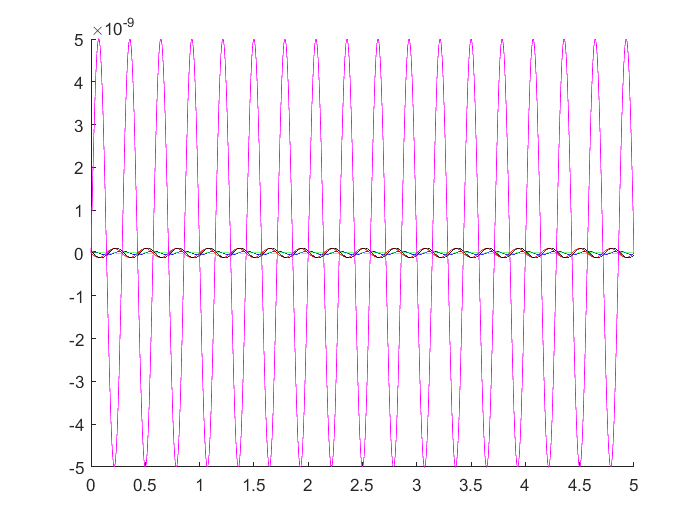


figure (1) ; clf
hold on
plot(t, Ta_I, 'r')
plot(t, Ta_C, 'b')
plot(t, Tb, 'G')
plot(t, T, 'k')
plot(t, T_w, 'm')